# PRACTICA 6. SERVICIOS TELEMATICOS MULTIMEDIA

% Guillermo Aldrey Pastor

% Fecha de Entrega: 27/11/2020

% En este archivo "practica6.m" se procede a la resolucion de la practica.
% En este caso voy a probar un nuevo metodo de presentacion en el que se 
% comentara la explicacion de cada apartado en el explica en un live script
% que luego convertire a PDF. 

clc;clear all;close all;

## 1. Elegir una imagen y representarla

%Lectura de la imagen
original=imread('marado.jpg');
original=im2double(original);
original = original(1:1200,1:1104,:);

figure 
imshow(original)

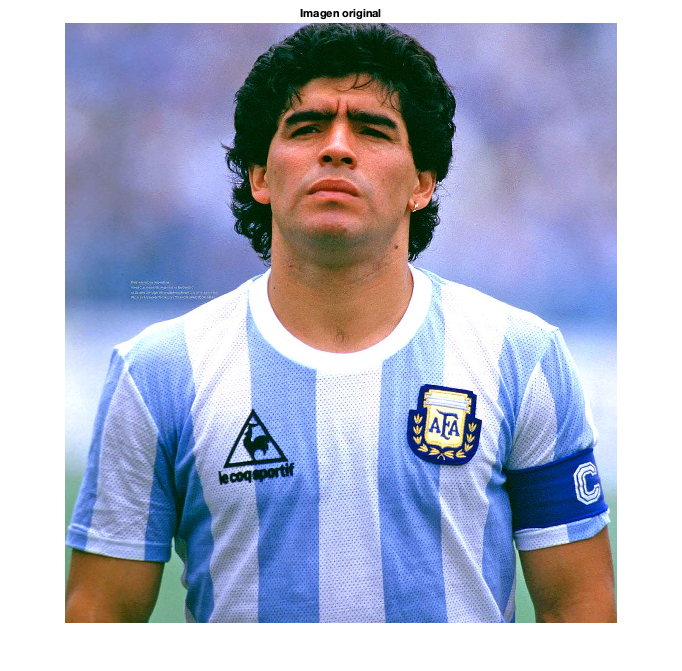

title('Imagen original')

## 2. Transformar la imagen en coordenadas YCbCr

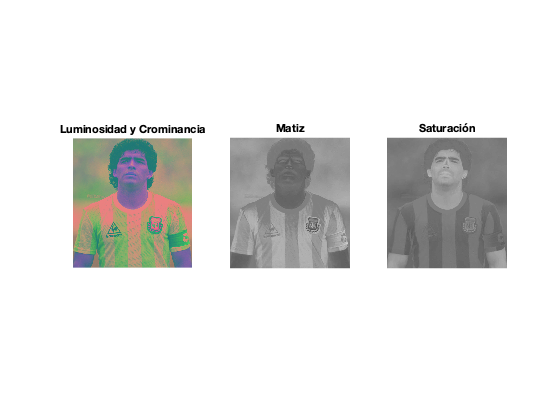

% Tablas de quantización
q_max = 255;
q_y = [16 11 10 16 124 140 151 161;
12 12 14 19 126 158 160 155;
14 13 16 24 140 157 169 156;
14 17 22 29 151 187 180 162;
18 22 37 56 168 109 103 177;
24 35 55 64 181 104 113 192;
49 64 78 87 103 121 120 101;
72 92 95 98 112 100 103 199] ;

q_c = [17 18 24 47 99 99 99 99 ;
18 21 26 66 99 99 99 99 ;
24 26 56 99 99 99 99 99 ;
47 66 99 99 99 99 99 99 ;
99 99 99 99 99 99 99 99 ;
99 99 99 99 99 99 99 99 ;
99 99 99 99 99 99 99 99 ;
99 99 99 99 99 99 99 99] ;

% Escala las matrices de cuantización según un factor de escala
qf = 75 ;
if qf < 50
    q_scale = floor (5000/ qf) ;
else
    q_scale = 200 - 2 * qf;
end

q_y = round (q_y * q_scale / 100);
q_c = round (q_c * q_scale / 100);

% Conversion RGB a Luminosidad y Crominancia (YCbCr)
ycc = rgb2ycbcr(im2double (original)) ;

figure
subplot(1,3,1)
imshow(ycc)
title('Luminosidad y Crominancia')
subplot(1,3,2)
imshow(ycc(:,:,2))
title('Matiz')
subplot(1,3,3)
imshow(ycc(:,:,3))
title('Saturación')


% Submuestrear y reducir crominancia
cb = conv2(ycc(:,:,2),[ 1 1 ; 1 1]) ./ 4.0;
cr = conv2(ycc(:,:,3),[ 1 1 ; 1 1]) ./ 4.0;
cb = cb(2:2: size(cb,1), 2 : 2 : size(cb,2));
cr = cr(2:2: size(cr,1), 2 : 2 : size(cr,2));
y = ycc(:,:,1);

## CONCLUSION

Hemos convertido nuestra imagen original de color de RGB a Luminosidad y Crominancia (YCbCr). Recordemos que la Luminancia (Y) esta relacionada con la sensibilidad del brillo del ojo humano, y la crominancia (CbCr) se caracteriza por dos atributos: matiz y saturacion. Acto seguido remuestreamos esta imagen creando pixels de mas baja resolucion, para poder realizar despues la DCT. Este ultimo paso no se hace con la luminancia ya que su empleo es jerarquico.

## 3. Realizar la DCT y DTC inversa a la imagen

% Matrices de Transformación
dct_matriz = dctmtx(8);
dct = @(block_struct) dct_matriz * block_struct.data* dct_matriz';
idct = @(block_struct) dct_matriz' * block_struct.data* dct_matriz;

% DCT con escalado antes de cuantización
y= blockproc(y,[8 8],dct).*q_max;
cb = blockproc(cb, [8 8], dct ) .* q_max;
cr = blockproc(cr, [8 8], dct ) .* q_max;

figure
imshow(y)

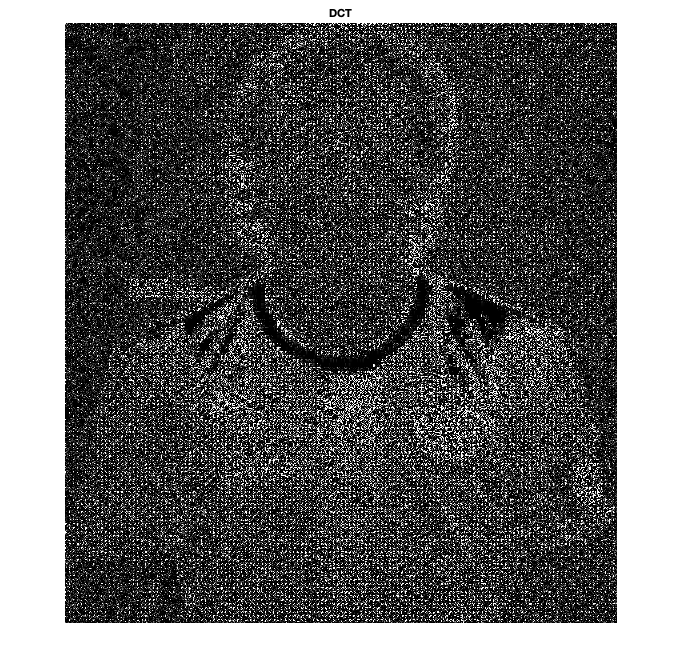

title('DCT')


% IDCT antes de la cuantización

yI = blockproc(y./q_max, [8 8], idct);
cbI = blockproc(cb./q_max, [8 8], idct);
crI = blockproc(cr./q_max, [8 8], idct);

figure;
imshow(yI);

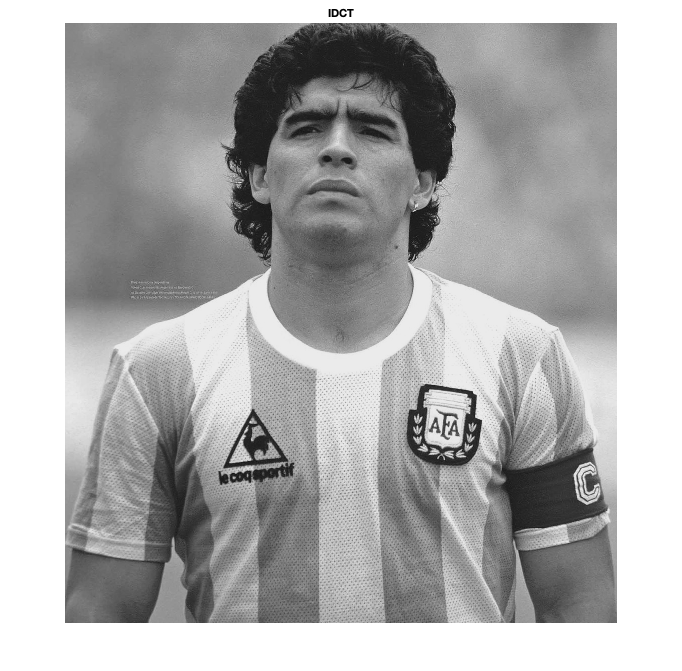

title('IDCT');

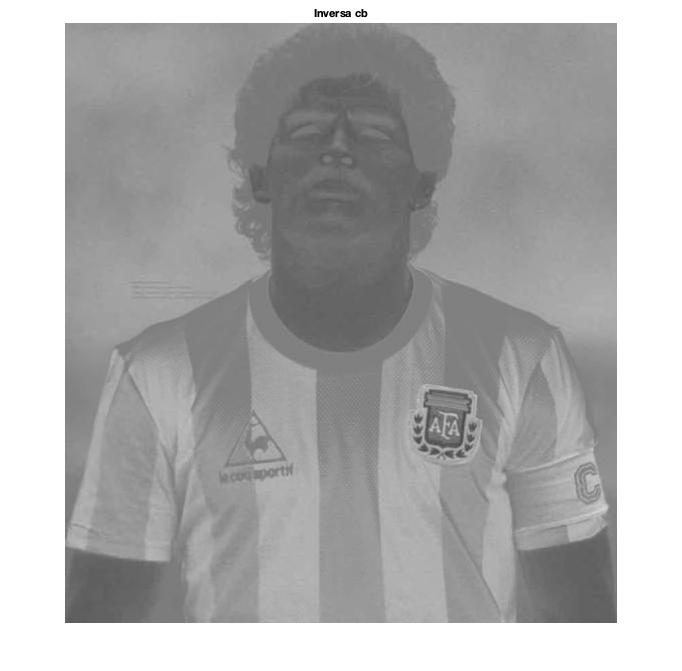


figure;
imshow(cbI);
title('Inversa cb');

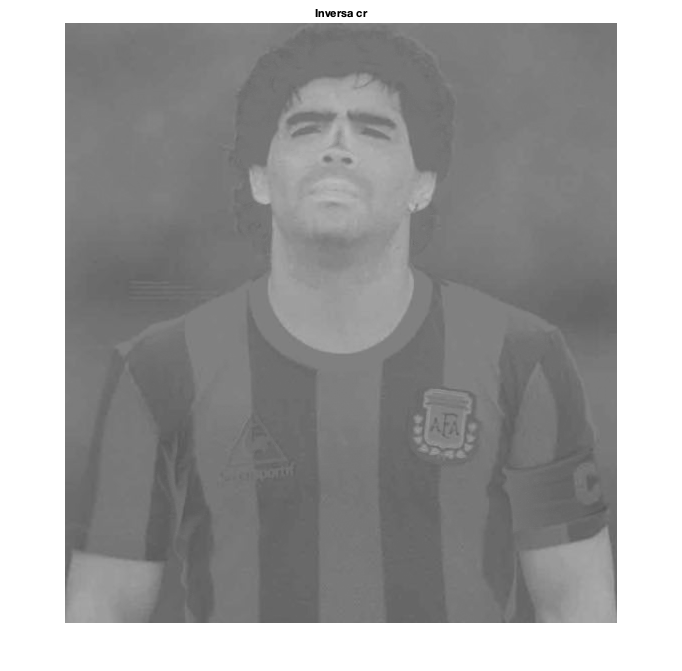


figure;
imshow(crI);
title('Inversa cr');

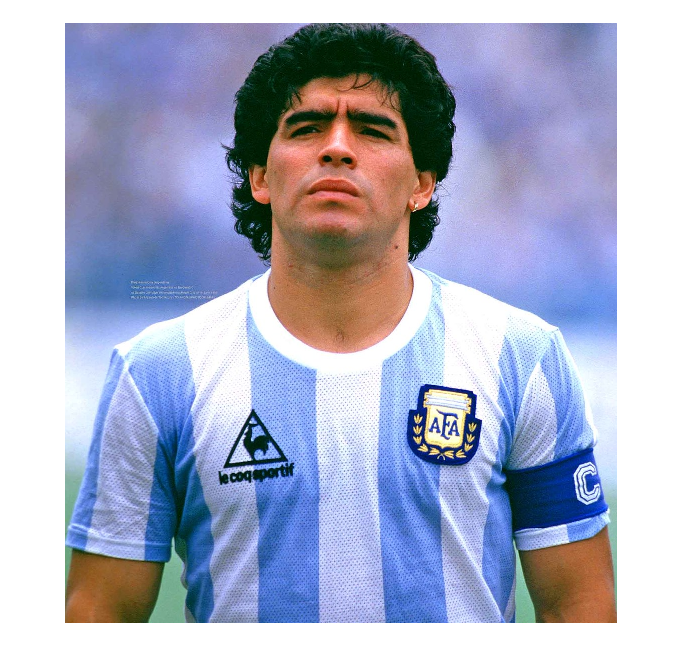


% Reconstruir la imagen
filtro_recupera_1d = [ 1 3 3 1 ] / 4;
filtro_recupera = filtro_recupera_1d'*filtro_recupera_1d;

cbI = conv2(filtro_recupera,upsample(upsample(padarray(cbI,[1 1],'replicate'),2)',2)');
cbI = cbI(4:size(cbI,1)-4, 4:size(cbI,2)-4);

crI = conv2(filtro_recupera,upsample(upsample(padarray(crI,[1 1],'replicate'),2)',2)');
crI = crI(4:size(crI,1)- 4,4:size(crI,2) - 4);

% Concatena canales y recupera
imagen_recI = ycbcr2rgb(cat(3,yI,cbI,crI));

figure(5), imshow(imagen_recI);

## CONCLUSION:

Los pixels que obtuvimos en el apartado anterior, se agrupan en grupos de 8x8, para poder aplicar la DCT a cada bloque.Si el número de filas y columnas no es múltiplo de 8, la fila de más abajo o la columna de más a la derecha se duplican hasta conseguir esa condición. JPEG eligió la DCT porque no asume nada en la estructura de datos que se le presentan. Como podemos observar, el proceso de DCT inversa funciona a la perfección pues obtenemos la imagen original, aplicando un filtro para ello, concatenando las componentes YCbCr inversas obtenidas.

## 4. Realizar la cuantizacion a la imagen.

% Cuantizacion de los coeficientes DCT
y= blockproc(y,[8 8],@(block_struct) round(round(block_struct.data)./q_y));
cb = blockproc(cb,[8 8],@(block_struct) round(round(block_struct.data)./q_c));
cr = blockproc(cr,[8 8],@(block_struct) round(round(block_struct.data)./q_c));

mask = [1   1   1   1   0   0   0   0
        1   1   1   0   0   0   0   0
        1   1   0   0   0   0   0   0
        1   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0
        0   0   0   0   0   0   0   0];
y = blockproc(y,[8 8],@(block_struct) mask .* block_struct.data);
cb = blockproc(cb,[8 8],@(block_struct) mask .* block_struct.data);
cr = blockproc(cr,[8 8],@(block_struct) mask .* block_struct.data);

figure;
imshow(y);

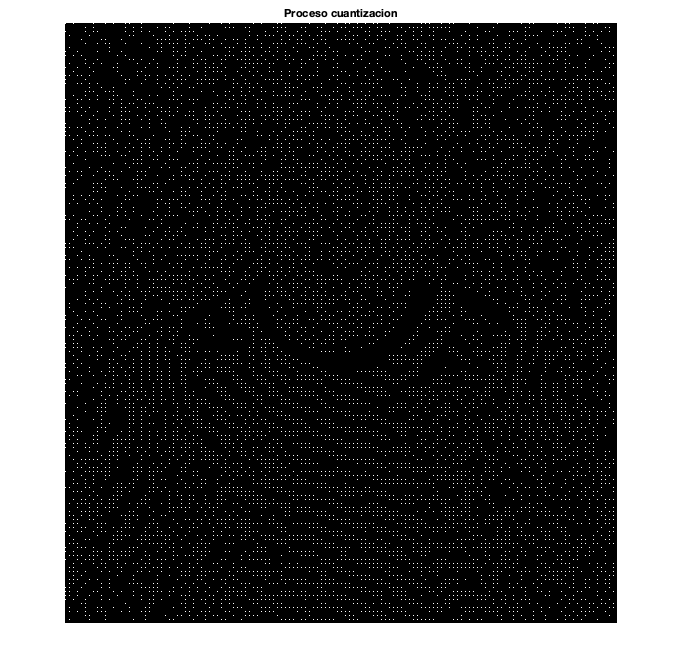

title('Proceso cuantizacion');

 

% Descuantizacion de los coeficientes DCT
yD = blockproc(y,[8 8],@(block_struct) block_struct.data.* q_y);
cbD = blockproc(cb,[8 8],@(block_struct) block_struct.data.* q_c);
crD = blockproc(cr,[8 8],@(block_struct) block_struct.data.* q_c);

figure;
imshow(yD);

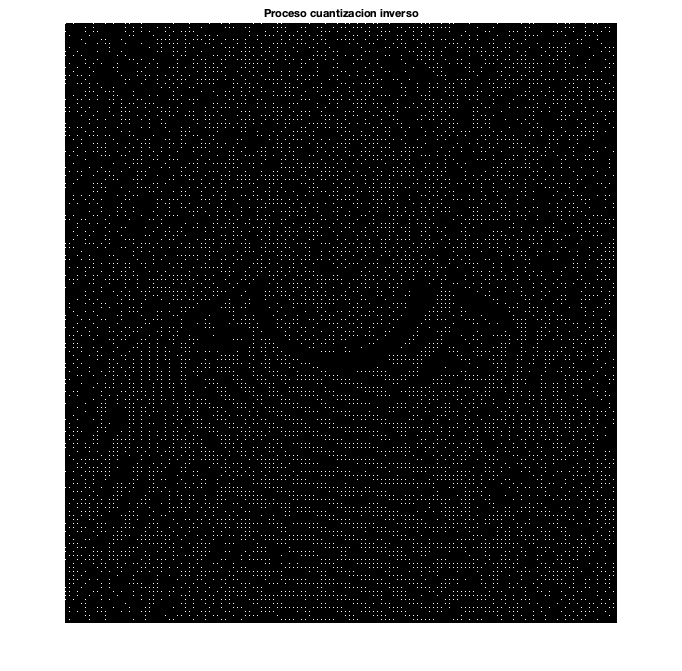

title('Proceso cuantizacion inverso');

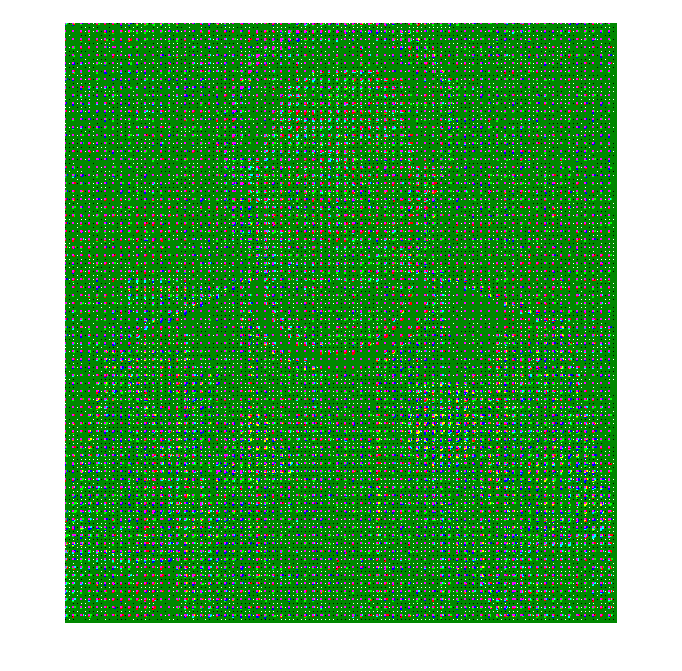


% Reconstruir la imagen
filtro_recupera_1d = [ 1 3 3 1 ] / 4;
filtro_recupera = filtro_recupera_1d'*filtro_recupera_1d;

cbD = conv2(filtro_recupera,upsample(upsample(padarray(cbD,[1 1],'replicate'),2)',2)');
cbD = cbD(4:size(cbD,1)-4, 4:size(cbD,2)-4);

crD = conv2(filtro_recupera,upsample(upsample(padarray(crD,[1 1],'replicate'),2)',2)');
crD = crD(4:size(crD,1)- 4,4:size(crD,2) - 4);

% Concatena canales y recupera
imagen_recD = ycbcr2rgb(cat(3,yD,cbD,crD));

figure(5), imshow(imagen_recD);

## CONCLUSION:

En este apartado hemos aplicado la cuantizacion a los coeficientes DCT, que tiene como objetivo reducir el numero total de bits en la imagen comprimida. Se observa claramente que aqui se producen perdidas de informacion, ya que no recuperamos la imagen original al 100%, al contrario que lo que sucedia sin cuantizar.

## 5. Realizar la codificacion en ZigZag

%Orden análisis para zigzag
    order = [1 9  2  3  10 17 25 18 11 4  5  12 19 26 33  ...
        41 34 27 20 13 6  7  14 21 28 35 42 49 57 50  ...
        43 36 29 22 15 8  16 23 30 37 44 51 58 59 52  ...
        45 38 31 24 32 39 46 53 60 61 54 47 40 48 55  ...
        62 63 56 64];
    
    ZigZag_Order = uint8([
            1  9  2  3  10 17 25 18
            11 4  5  12 19 26 33 41
            34 27 20 13 6  7  14 21 
            28 35 42 49 57 50 43 36 
            29 22 15 8  16 23 30 37
            44 51 58 59 52 45 38 31 
            24 32 39 46 53 60 61 54 
            47 40 48 55 62 63 56 64]);

% Zigzag de los bloques

bloques = im2col(y, [8 8], 'distinct');  % Pone los bloques de 8x8 en columnas
xb = size(bloques, 2);                   % Coge el numero de bloques
bloques_zigzag = bloques(order, :);      % Reordena elementos columna

coef_DC= bloques_zigzag(1,:);
coef_AC= bloques_zigzag(2:63,:);

disp(y);

  Columns 1 through 22

   132     0    -1     0     0     0     0     0   132    -1    -1     0     0     0     0     0   133    -1     1     0     0     0
     0     1     0     0     0     0     0     0    -1    -1    -1     0     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     0     0    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0   

disp(bloques_zigzag);

  Columns 1 through 22

   132   133   134   133   133   133   133   133   133   133   133   135   137   140   143   145   148   151   152   153   153   156
     0     1     1     0     0     0     1     1     0     0     1     1     0     1     0     1     1     0     1     0     1     0
     0     1     0     1     0     0     0    -1    -1     0     0    -3    -1     1    -1     1    -1    -1     0     0    -2    -1
     0     0     0    -1     0     0     0     0     0     0     0     0     1     0     0     0     0     1     1    -1     0     0
     1     0     1     0     0     0    -1     1     1     0    -1     1    -1     1     2     1    -1    -1    -1     1     0     1
    -1     0     0     0     0     0     0    -1     0     0     0    -1     0     1     1    -1     1     0     1     0    -1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0   

## CONCLUSION

Este paso es importante para la compresion de JPEG ya que los 64 coeficientes resultante de la DCT cuantificados se ordenan segun zig-zag para luego cofidicarlos usando RLE y Huffman. Mostramos tanto los bloques en su version original como el resultado de la codificacion zigzag.

## 6. Codificacion de Entropia. DCPM, HUFFMAN. Indicar tamaño tras codificacion

stream=[];
dpcm(1,1)=coef_DC(1);
stream=cat(2,stream,huffman_dc(dpcm(1,1)),huffman_ac(coef_AC(:, 1)));
for m=2:xb
    dpcm(m,1)=coef_DC(m)-coef_DC(m-1);
    stream=cat(2,stream,huffman_dc(dpcm(m,1)),huffman_ac(coef_AC(:,m)));
end
   
eob = max(bloques_zigzag(:)) + 1;               % Create end-of-block symbol
r = zeros(numel(bloques_zigzag) + size(bloques_zigzag, 2), 1);
count = 0;
for j = 1:xb                       % Process 1 block (col) at a time
   i = max(find(bloques_zigzag(:, j)));         % Find last non-zero element
   if isempty(i)                   % No nonzero block values
      i = 0;
   end
   p = count + 1;
   q = p + i;
   r(p:q) = [bloques_zigzag(1:i, j); eob];      % Truncate trailing 0's, add EOB,
   count = count + i + 1;          % and add to output vector
end

r((count + 1):end) = [];           % Delete unusued portion of r
quality=1;
[zm, zn] = size(y); 
z           = struct;
z.size      = uint16([zm zn]);
z.numblocks = uint16(xb);
z.quality   = uint16(quality * 100);

% hacer mex unravel.c (previamente)

z_huffman   = mat2huff(r);

## CONCLUSION.

Ahora pasamos a la codificacion de la entropia de los coeficientes DCT discretizados. Se codifican los coeficientes CD y los coeficientes AC, tratando a las dos componentes de forma distinta.

## 7. Mostrar y comprobar cómo quedaría la imagen tras decodificarla.

pause

rev = order;                          % Calcula orden inverso
for k = 1:length(order)
   rev(k) = find(order == k);
end

q_y = double(z.quality) / 100 * q_y;  % Recupera calidad si fue disminuida.
xb = double(z.numblocks);             % Recupera número de bloques.
sz = double(z.size);
xn = sz(2);                           % Recupera columnas.
xm = sz(1);                           % Recupera filas.
x = huff2mat(z_huffman);              % Decodifica Huffman.

Undefined function or variable 'unravel'.

Error in huff2mat (line 58)
x = unravel(y.code', link, m * n);    % Decode using C 'unravel'

eob = max(x(:));                      % Coge el símbolo de fin de bloque

cero = zeros(64, xb);   k = 1;        % Construye columnas bloque copiando
for j = 1:xb                          % valores sucesivos desde x 
   for i = 1:64                       % en columnas de cero, cambiando 
      if x(k) == eob                  % a la siguiente columna si
         k = k + 1;   break;          % se encuentra un símbolo de fin de bloque (EOB).
      else
         cero(i, j) = x(k);
         k = k + 1;
      end
   end
end

cero = cero(rev, :);                           % Restaura orden
x = col2im(cero, [8 8], [xm xn], 'distinct');  % Forma bloques en la matriz
x = blkproc(x, [8 8], 'x .* P1', q_y);         % Desnormaliza con DCT
t = dctmtx(8);                                 % Coge bloques de 8 x 8 de la DCT
x = blkproc(x, [8 8], 'P1 * x * P2', t', t);   % Calcula bloque DCT-1
x = uint8(x + 128); 

figure
imshow(x)
title('Imagen recuperada')

imwrite(x,'Recuperada.jpg');

histogram(y);
histogram(x);

## CONCLUSION

Aqui se descomprime y se restaura la imagen siguiendo los pasos de decodificacion JPEG.

## 9. Evaluar la relacion señal-ruido

energia_imagen_original = sum( original(:,:,1).^2 );
imagen_ruido = sum( (original(:,:,1)-imagen_rec(:,:,1)).^2 );
SNR = energia_imagen_original/ imagen_ruido;

## CONCLUSION.

Obtenemos la relacion señal a ruido

## CONCLUSION GENERAL

No he sido capaz de conseguir la decodificacion final ni la SNR ya que en el Mac no me funcionaba la decodificacion de la funcion unravel.c, por lo tanto indico solamente como se harian los ultimos apartados.

Segunda practica de imagen en la que he aprendido los conceptos basados en JPEG, algo bastante curioso e importante. Me ha venido bien para afianzar los conceptos del tema y me ha parecido al igual de interesante que la practica anterior.